# Понижение частоты дискретизации в целое число раз

#### Формирование суммы двух гармонических сигналов с частотами 1000 Гц и 3400 Гц на частоте дискретизации fs = 30000 Гц:

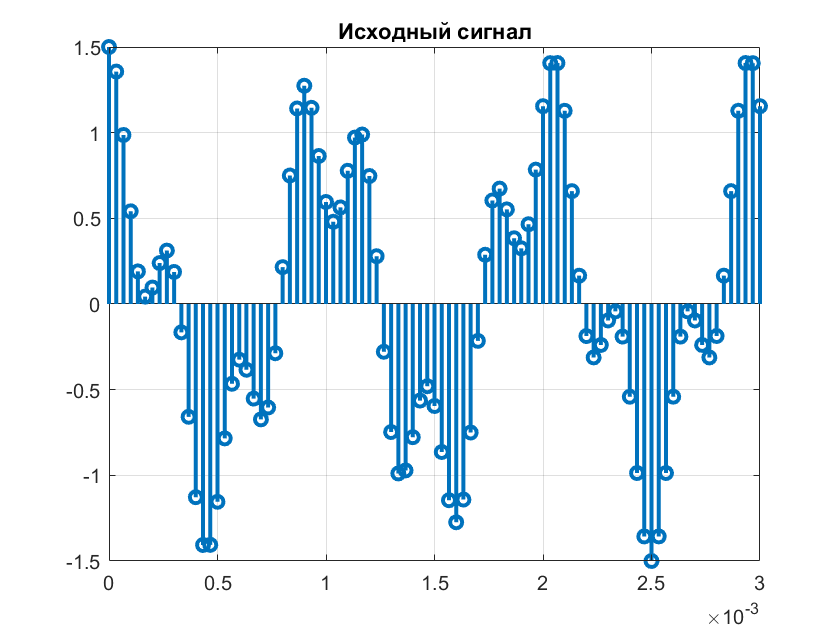

fs = 30000;
t1 = 0:1/fs:1;
f1 = 1000;
x1 = cos(2*pi*f1*t1);
f2 = 3400;
x2 = 0.5*cos(2*pi*f2*t1);
s = x1 + x2;
stem(t1,s,'LineWidth',2);
title('Исходный сигнал');
xlim([0 3e-3]);
grid on;

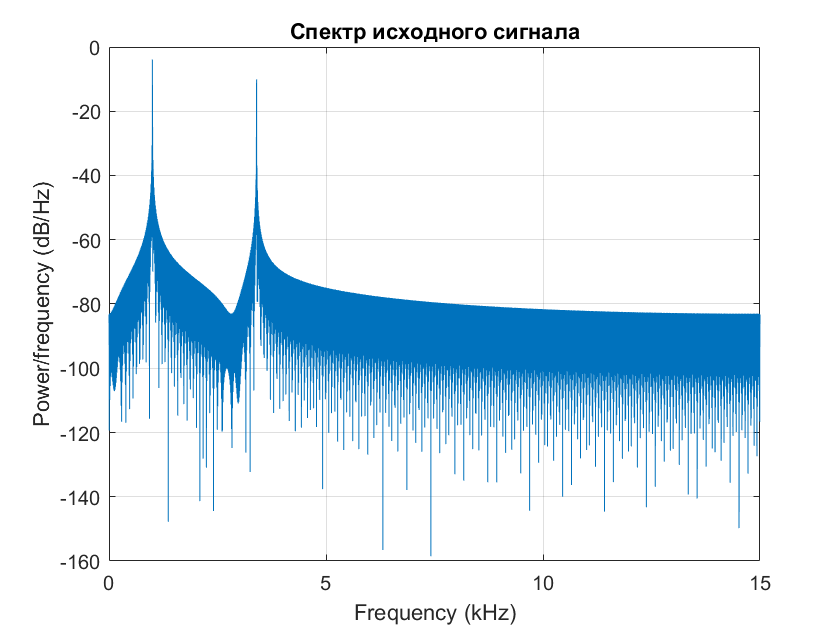

sound(s,fs);
periodogram(s,[],[],fs);
title('Спектр исходного сигнала');

#### Понижение частоты дискретизации методом downsample:

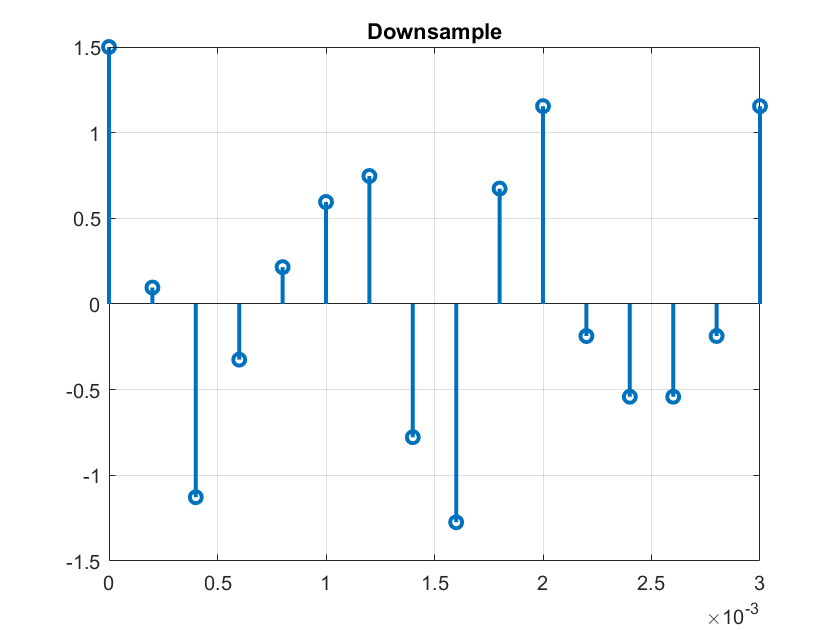

down = 6;
y_down = downsample(s,down);
t2 = 0:1/(fs/down):1;
stem(t2,y_down,'LineWidth',2);
title('Downsample');
xlim([0 3e-3]);
grid on;

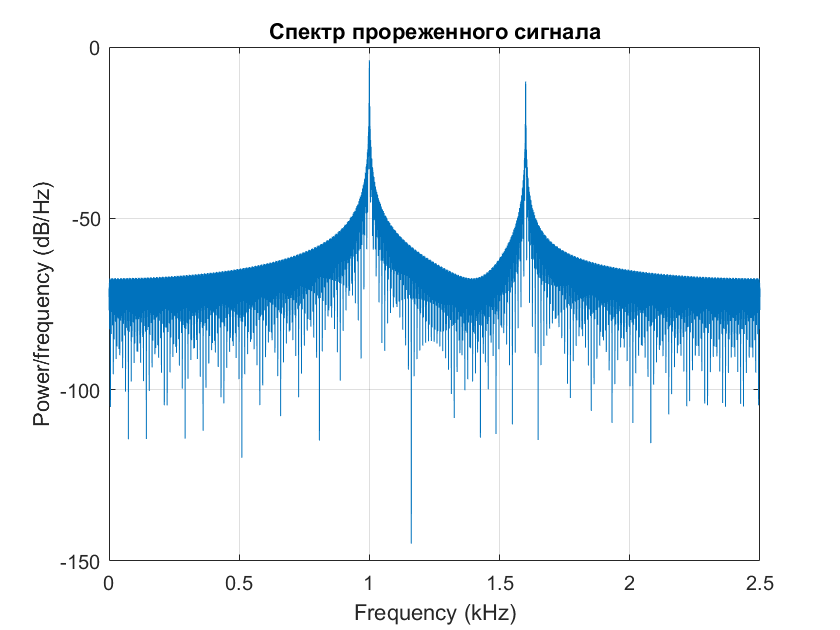

sound(y_down,fs/down);
periodogram(y_down,[],[],fs/down);
title('Спектр прореженного сигнала');

#### Понижение частоты дискретизации методом decimate:

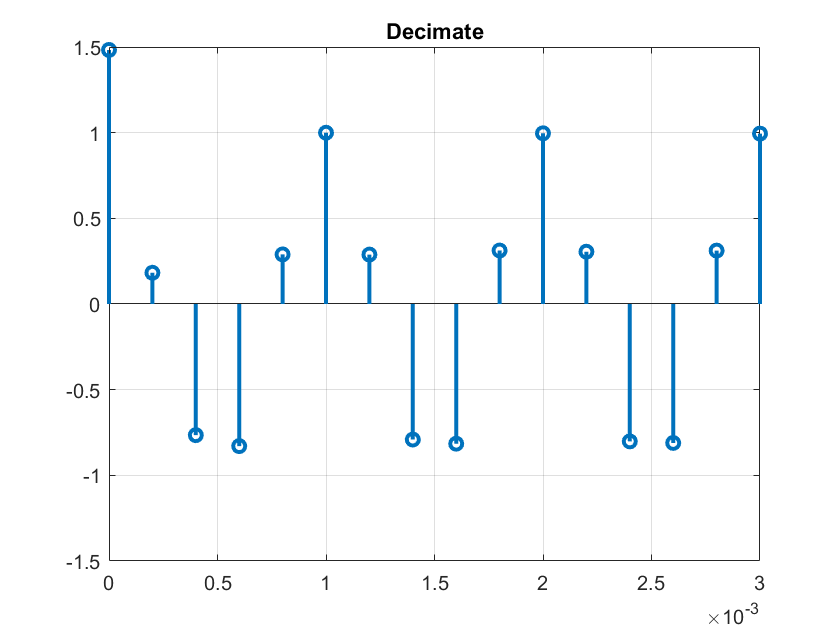

y_decim = decimate(s,down); 
stem(t2,y_decim,'LineWidth',2);
title('Decimate');
ylim([-1.5 1.5]);
xlim([0 3e-3]);
grid on;

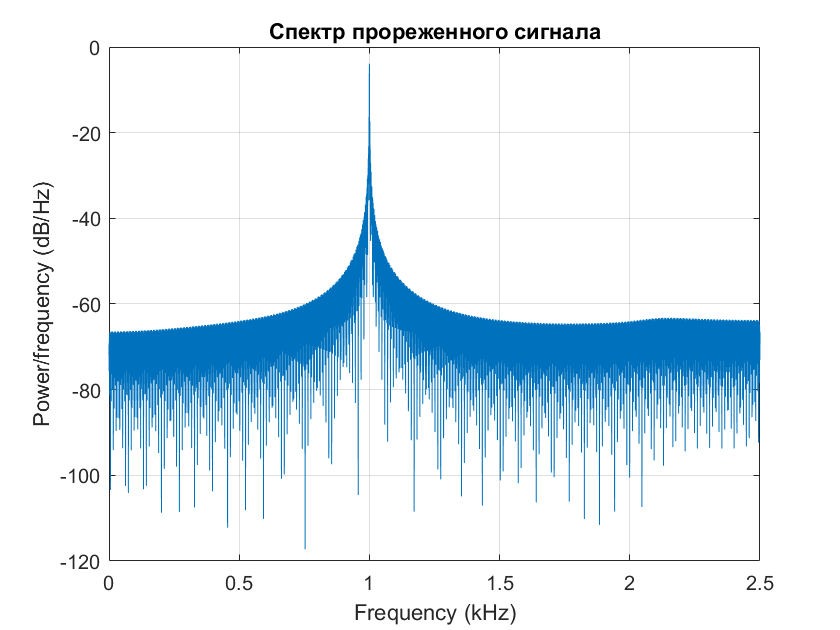

sound(y_decim,fs/down);
periodogram(y_decim,[],[],fs/down);
title('Спектр прореженного сигнала');